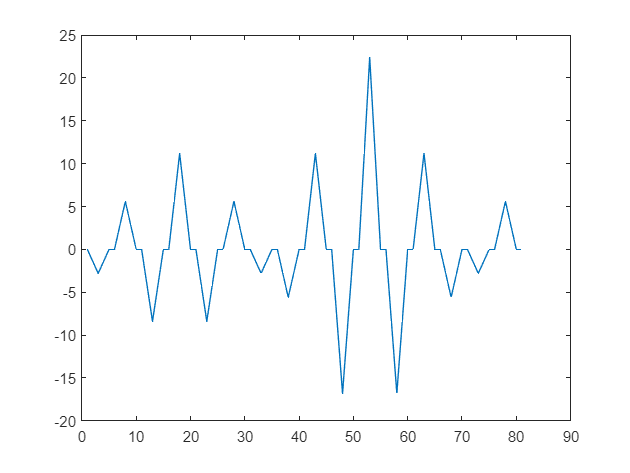

clear
load Apkirpta_ideali_preambule_d.mat %yy-ideali diferencijuota preambule
%Koreliacijos max priklausomybe nuo amplitudes

amplitude_duom = [];

rms_duom = [];
eng_duom = [];
langas_duom = [];
pastumimas_duom = [];

neteisingi_d = [];
viso_max_duom_d = [];
viso_max_duom2_d = [];
viso_neteisingi_d = [];
kiekvienas_max_d = [];
kiekvienas_max2_d = [];
kiekvienas_eng_d = [];

neteisingi_nd = [];
viso_max_duom_nd = [];
viso_max_duom2_nd = [];
viso_neteisingi_nd = [];
kiekvienas_max_nd = [];
kiekvienas_max2_nd = [];
kiekvienas_eng_nd = [];

viso_viso_rms = [];
viso_viso_eng = [];
viso_viso_langas = [];
viso_viso_pastumimas = [];
kiekvienas_eng = [];


pastumimasN = 2;
fdiskret = 10E6;
tdiskret = 1/fdiskret;
idealPreambule = [zeros(1, 5), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(2E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, 10)];
pastumtaPreambule = [zeros(1, pastumimasN), idealPreambule(1:length(idealPreambule)-pastumimasN)];
diferencijuotaPreambule = idealPreambule - pastumtaPreambule;

dataSend = "101101";
vienetu_generuoti = 1000;

%Ref itampa 1.4V
langas_temp = [];
pastumimas_temp = [];
%for langas = 70:10:100
for pastumimasN = 2%1:1:10
    langas = 50;
    amplitude_duom = [];
    rms_duom = [];
    eng_duom = [];
    preambules_max_duom = [];
    preambules_max_duom2 = [];
    langas_temp = [];
    neteisingi = 0;
    pastumimas_temp = [];
    temp_preambules_max1_error_max = [];
    temp_preambules_max1_error_min = [];
    temp_preambules_max2_error_max = [];
    temp_preambules_max2_error_min = [];

    for generuojama_amplitude = 0.5:0.05:1.4
        vienetai_d = 0;
        vienetai_nd = 0;
        
        nepataikyta_d = 0;
        nepataikyta_nd = 0;

        kiekvienas_max_temp_d = zeros(1, vienetu_generuoti);
        kiekvienas_max2_temp_d = zeros(1, vienetu_generuoti);
        
        kiekvienas_max_temp_nd = zeros(1, vienetu_generuoti);
        kiekvienas_max2_temp_nd = zeros(1, vienetu_generuoti);

        kiekvienas_eng_temp_d = zeros(1, vienetu_generuoti);
        kiekvienas_eng_temp_nd = zeros(1, vienetu_generuoti);
        
        for i = 1:vienetu_generuoti
            [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, generuojama_amplitude);
            
            ADCsignal2 = [ADCsignal];
            pastumtas = [zeros(1, pastumimasN), ADCsignal2(1:length(ADCsignal2)-pastumimasN)];
            diferencijuotasPilnas = ADCsignal2 - pastumtas;
           
            %y = GenerateConv(y, yy); %diferencijuotas DVIGUBAI
            y_d = GenerateConv(diferencijuotasPilnas, diferencijuotaPreambule); %diferencijuotas
            y_nd = GenerateConv(ADCsignal2, idealPreambule); %Nediferencijuoptas

            %TIkrinam diferencijuota
            [maksimumai, indeksai] = maxk(y_d(1:330),2);
            max_y = maksimumai(1);
            max_y2 = maksimumai(2);
            index_y = indeksai(1);
            if index_y > 310 && index_y < 316
                vienetai_d = vienetai_d + 1;

                kiekvienas_eng_temp_d(vienetai_d) = sum(abs(ADCsignal2(index_y-langas:index_y) .* ADCsignal2(index_y-langas:index_y)))/langas;
                kiekvienas_max_temp_d(vienetai_d)= max_y;
                kiekvienas_max2_temp_d(vienetai_d)= max_y2;
            else
                nepataikyta_d = nepataikyta_d + 1;
            end

             %TIkrinam NEdiferencijuota
            [maksimumai, indeksai] = maxk(y_nd(1:330),2);
            max_y = maksimumai(1);
            max_y2 = maksimumai(2);
            index_y = indeksai(1);
            if index_y > 310 && index_y < 316
                vienetai_nd = vienetai_nd + 1;

                kiekvienas_eng_temp_nd(vienetai_nd) = sum(abs(ADCsignal2(index_y-langas:index_y) .* ADCsignal2(index_y-langas:index_y)))/langas;
                kiekvienas_max_temp_nd(vienetai_nd)= max_y;
                kiekvienas_max2_temp_nd(vienetai_nd)= max_y2;
            else
                nepataikyta_nd = nepataikyta_nd + 1;
            end
            
        end

        kiekvienas_max_d = [kiekvienas_max_d; kiekvienas_max_temp_d];
        kiekvienas_max2_d = [kiekvienas_max2_d; kiekvienas_max2_temp_d];
        kiekvienas_eng_d = [kiekvienas_eng_d; kiekvienas_eng_temp_d];

        kiekvienas_max_nd = [kiekvienas_max_nd; kiekvienas_max_temp_nd];
        kiekvienas_max2_nd = [kiekvienas_max2_nd; kiekvienas_max2_temp_nd];
        kiekvienas_eng_nd = [kiekvienas_eng_nd; kiekvienas_eng_temp_nd];

        neteisingi_d = [neteisingi_d, nepataikyta_d];
        neteisingi_nd = [neteisingi_nd, nepataikyta_nd];
       
        %{
        [a, ~] = max(sugeneruoti_max);
        temp_preambules_max1_error_max = [temp_preambules_max1_error_max, a];
        [a, ~] = min(sugeneruoti_max);
        temp_preambules_max1_error_min = [temp_preambules_max1_error_min, a];
    
        [a, ~] = max(sugeneruoti_max2);
        temp_preambules_max2_error_max = [temp_preambules_max2_error_max, a];
        [a, ~] = min(sugeneruoti_max2);
        temp_preambules_max2_error_min = [temp_preambules_max2_error_min, a];
        %}
    
        amplitude_duom = [amplitude_duom, generuojama_amplitude];
        langas_temp = [langas_temp, langas];
        pastumimas_temp = [pastumimas_temp, pastumimasN];
    end
    %preambules_max1_error_max = [preambules_max1_error_max; temp_preambules_max1_error_max];
    %preambules_max1_error_min = [preambules_max1_error_min; temp_preambules_max1_error_min];
    %preambules_max2_error_max = [preambules_max2_error_max; temp_preambules_max2_error_max];
    %preambules_max2_error_min = [preambules_max2_error_min; temp_preambules_max2_error_min];
    
    viso_neteisingi_d = [viso_neteisingi_d; neteisingi_d];
    viso_neteisingi_nd = [viso_neteisingi_nd; neteisingi_nd];

    viso_viso_langas = [viso_viso_langas; langas_temp];
    viso_viso_pastumimas = [viso_viso_pastumimas; pastumimas_temp];
   
    langas_duom = [langas_duom, langas];
    pastumimas_duom = [pastumimas_duom, pastumimasN];
end
plot(yy)

viso_max_duom_d = mean(kiekvienas_max_d, 2)';
viso_max_duom_nd = mean(kiekvienas_max_nd, 2)';

viso_max_duom2_d = mean(kiekvienas_max2_d, 2)';
viso_max_duom2_nd = mean(kiekvienas_max2_nd, 2)';

viso_eng_duom_d =  mean(kiekvienas_eng_d, 2)';
viso_eng_duom_nd =  mean(kiekvienas_eng_nd, 2)';


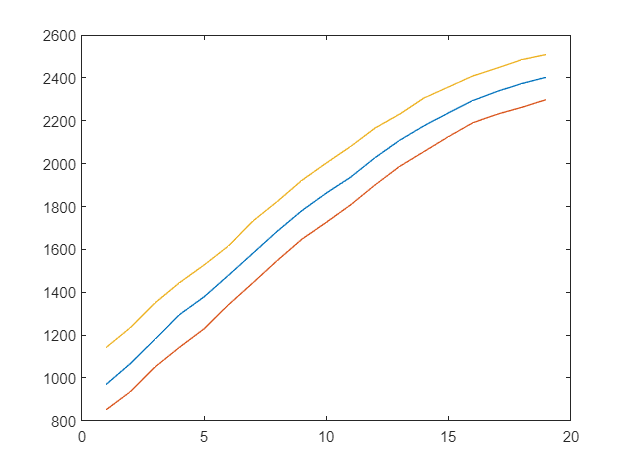


%norm_preambules_max1_error_min = abs(viso_max_duom - preambules_max1_error_min);
%norm_preambules_max1_error_max = abs(preambules_max1_error_max - viso_max_duom);
%norm_preambules_max2_error_min = abs(viso_max_duom2 - preambules_max2_error_min);
%norm_preambules_max2_error_max = abs(preambules_max2_error_max - viso_max_duom2);

viso_max_duom = viso_max_duom_d;
viso_max_duom2 = viso_max_duom2_d;
kiekvienas_max = kiekvienas_max_d;
kiekvienas_eng = kiekvienas_eng_d;

viso_viso_eng = viso_eng_duom_d;

viso_skirtumas = viso_max_duom - viso_max_duom2;

%skirtumasLowHigh = (preambules_max1_error_min - preambules_max2_error_max) ./ viso_max_duom;

%kiekvienas_skirtumas = kiekvienas_max - kiekvienas_max2;
%kiekvienas_mean = mean(kiekvienas_skirtumas);
%kiekvienas_mean_skirtumas = kiekvienas_skirtumas - kiekvienas_mean;

%kiekvienas_max_deviacija = mean(kiekvienas_max) - kiekvienas_max;

minKvantiliai = [];
maxKvantiliai = [];
for i = 1:19
    minKvantiliai = [minKvantiliai, nonzeros(quantile(kiekvienas_max(i, :), 0.25))];
    maxKvantiliai = [maxKvantiliai, nonzeros(quantile(kiekvienas_max(i, :), 0.75))];
end
plott = mean(kiekvienas_max, 2);
plot(plott)

hold on
plot(minKvantiliai)
plot(maxKvantiliai)
hold off

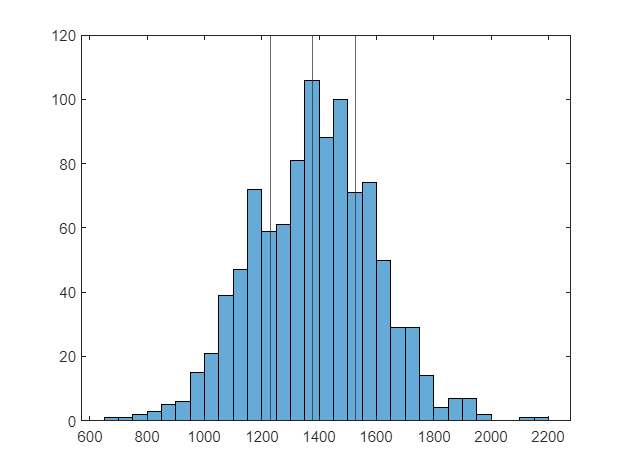

rodomasIndex = 5;

histogramai = nonzeros(kiekvienas_max(rodomasIndex, :));

histograma = histogram(histogramai);
hold on
xline(minKvantiliai(rodomasIndex))
xline(maxKvantiliai(rodomasIndex))
xline(mean(kiekvienas_max(rodomasIndex, :)))
hold off

rodomasIndex = 1;
rangeas = 1:19;

%p = polyfit([0, viso_viso_eng(rodomasIndex, :)], [0, viso_max_duom(rodomasIndex, :)], 2);
%p = polyfit(viso_viso_eng(rodomasIndex, rangeas), viso_max_duom(rodomasIndex, rangeas)-norm_preambules_max1_error_min(rodomasIndex, rangeas), 2);
p = polyfit([0, viso_viso_eng(1, :)], [1800, viso_max_duom(1, :)], 2);
%p = polyfit([0, viso_viso_eng(rodomasIndex, rangeas)], [1000, maxKvantiliai(rodomasIndex, rangeas)], 2);
p

p = 	1.0e+03 *

    0.0000   -0.0001    1.5739


p_fit_x = 0:1000:25000;
p_fit = polyval(p, p_fit_x);
p_fitt = 2000^2*p(1)+2000*p(2)+p(3)%-1285.4 + 3000*1.0267

p_fitt = 1.4307e+03

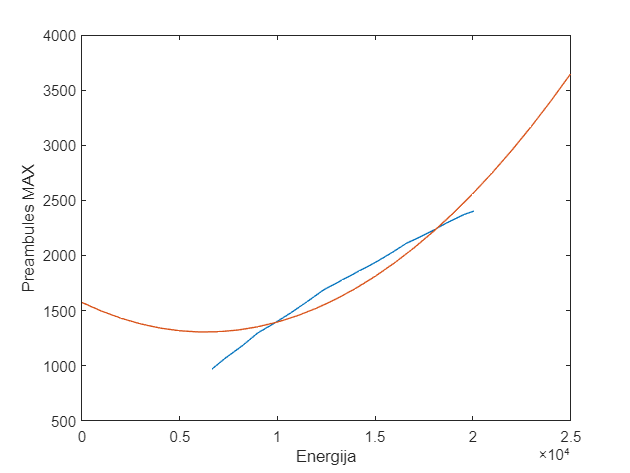

plot(viso_viso_eng(rodomasIndex, :), viso_max_duom(rodomasIndex, :))
xlabel("Energija")
ylabel("Preambules MAX")
hold on
plot(p_fit_x, p_fit)
hold off

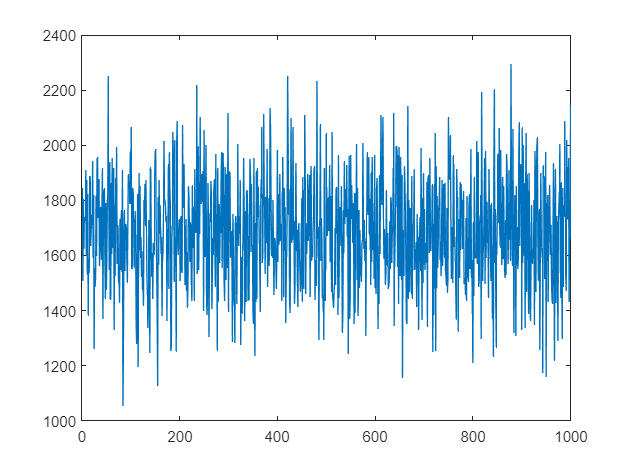


figure
plot(kiekvienas_max(8, :))
hold on

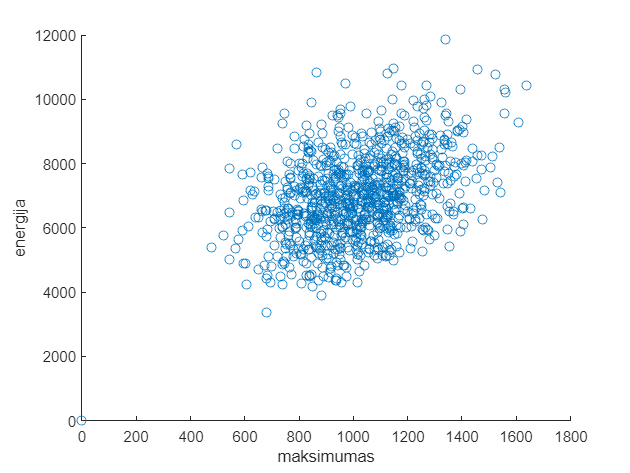


figure
scatter(kiekvienas_max(1, :), kiekvienas_eng(1, :))
xlabel("maksimumas")
ylabel("energija")

R = corr2(kiekvienas_max(8, :), kiekvienas_eng(8, :))

R = 0.3876


figure
plot(kiekvienas_skirtumas(rodomasIndex, :))

Unrecognized function or variable 'kiekvienas_skirtumas'.

hold on
plot(movmean(kiekvienas_skirtumas(rodomasIndex, :), 50))
xlabel("Atskaitos")
ylabel("Skirtumas")
legend("Skirtumas tarp peaku", "Slenkantis vidurkis")
hold off
plot(kiekvienas_mean_skirtumas(rodomasIndex, :))
hold on
yline(kiekvienas_mean(rodomasIndex))
hold off

figure
%errorbar(amplitude_duom, preambules_max_duom, preambules_max1_error_min, preambules_max1_error_max)

%errorbar(amplitude_duom, preambules_max_duom2, preambules_max2_error_min, preambules_max2_error_max)
%legend(["Maksimumas 1", "Maksimumas 2"])
legend()
hold off

figure
%plot(rms_duom, viso_neteisingi(rodomasIndex, 2:length(viso_neteisingi)))
%plot(rms_duom, viso_neteisingi)
xlabel("RMS")
ylabel("Neteisingu peaku skaicius is 100")
errorbar(rms_duom, viso_max_duom(rodomasIndex, :), norm_preambules_max1_error_min(rodomasIndex, :), norm_preambules_max1_error_max(rodomasIndex, :))
xlabel("RMS signalo")
ylabel("Preambules MAX")
hold on
errorbar(rms_duom, viso_max_duom2(rodomasIndex, :), norm_preambules_max2_error_min(rodomasIndex, :), norm_preambules_max2_error_max(rodomasIndex, :))
legend(["Maksimumas 1", "Maksimumas 2"])
hold off
figure
plot(rms_duom, skirtumasLowHigh(rodomasIndex, :))
xlabel("RMS signalo")
ylabel("Skirtumas tarp preambules min ir antro peako max")

figure
plot(rms_duom, viso_skirtumas(rodomasIndex, :))
xlabel("RMS signalo")
ylabel("Skirtumas tarp amksimumu")
%Pavirsius nuo pastumimo, rms ir skirtumo tarp peaku, turi sugeneruoti
%pastumima visa
surf(rms_duom, pastumimas_duom, viso_skirtumas)
%surf(rms_duom, langas_duom , viso_skirtumas)
%surf(eng_duom, langas_duom , viso_skirtumas)
xlabel("RMS");
ylabel("Pastumimas");
zlabel("Skirtumas");
figure
%scatter3(viso_viso_rms(:), viso_viso_langas(:), viso_skirtumas(:), 10, viso_skirtumas(:))
%scatter3(viso_viso_eng(:), viso_viso_langas(:), viso_skirtumas(:), 10, viso_skirtumas(:))
scatter3(viso_viso_pastumimas(:), viso_viso_rms(:), viso_skirtumas(:), 10, viso_skirtumas(:))
xlabel("X RMS")
ylabel("Y Lango ilgis")
zlabel("Z Skirtumas")